#### PROGRAMA ELABORADO POR : ÑOL IVAN JUAN DE DIOS ROJAS (TJGO)

- `Progama para la solución de sistemas de ecuaciones no lineales (SENL), por el metodo de Broyden.`

clc;clear;close all;syms x;syms y;syms z;syms x1;syms x2;syms y1;syms y2;syms z1;syms z2;
% ====================================================================
text = {'Ingrese N° de ecuaciones:  ','Cantidad de variable:','Valores iniciales,Entre espacios 2 3 4 5. ','Toleracia:','Numero maximo de Iteraciones:'};
dlgtitle = 'S.E.N.O. - NEWTON RHAPSON';
dimensions = [1 18; 1 50; 1 40; 1 29; 1 60];
default_input = { '3','3','0.1 0.1 -0.1','10^-8','10' };
answer = inputdlg(text,dlgtitle,dimensions,default_input);
num_equ=str2num(answer{1}) ; num_var=str2num(answer{3}) ;
% ====================================================================
% ====================================================================
equs={'1'}; 
% vari={'x'};
diff_equs=["-","-"];
% ====================================================================
% ====================================================================
% ====================================================================
% for j=1:1:num_equ
% j_equ = num2str(j) ; 
% text_var = {j_equ};
% dlgtitle_var = 'INGRESE LA VARIABLE N°';
% dimensions_var = [1 50];
% default_input_var = { '0' };
% answer_var = inputdlg(text_var,dlgtitle_var,dimensions_var,default_input_var);
% vari{j}=answer_var;
% str2sym(vari{j})
% end

% ====================================================================
% ====================================================================
% ====================================================================
 symss={'y';'y'};
 matrixx=str2sym(symss);

for i=1:1:num_equ
i_equ = num2str(i);
text_equ = {i_equ};
dlgtitle_equs = 'INGRESE LA ECUACIÓN N°';
dimensions_equs = [1 50];
default_input_equ = { '0' };
answer_equs = inputdlg(text_equ ,dlgtitle_equs,dimensions_equs,default_input_equ);
equs{i}=answer_equs;
diff_equs(i)=string(equs{i});
matrixx(i)=eval(diff_equs(i)');
end
   matrixx % MATRIZ DEL SISTEMA DE ECUACIONES

$$matrixx = \left(\begin{array}{c} 3\,x-\cos\left(y\,z\right)-\frac{1}{2}\\ \sin\left(z\right)-81\,{\left(y+\frac{1}{10}\right)}^{2}+x^{2}+\frac{53}{50}\\ 20\,z+{\mathrm{e}}^{-x\,y}+\frac{5332248173269055}{562949953421312} \end{array}\right)$$

 MatrizJacobiana = jacobian(matrixx) % JACOBIANO DEL SISTEMA DE ECUACIONES

$$MatrizJacobiana = \left(\begin{array}{ccc} 3 & z\,\sin\left(y\,z\right) & y\,\sin\left(y\,z\right)\\ 2\,x & -162\,y-\frac{81}{5} & \cos\left(z\right)\\ -y\,{\mathrm{e}}^{-x\,y} & -x\,{\mathrm{e}}^{-x\,y} & 20 \end{array}\right)$$

 x=num_var(1); %#ok<NASGU> % OBTENEMOS EL VALOR X INCIAL
   y=num_var(2); %#ok<NASGU> % OBTENEMOS EL VALOR Y INCIAL
   z=num_var(3); %#ok<NASGU> % OBTENEMOS EL VALOR Z INCIAL
   nn=eval(matrixx)  % EVALUAMOS EL SISTEMA CON LOS VALORES INCIALES

nn =    -1.2000
   -2.2698
    8.4620


mm=eval(MatrizJacobiana) % EVALUAMOS EL JACOBIANO DEL SISTEMA CON LOS VALORES INICIALES

mm =     3.0000    0.0010   -0.0010
    0.2000  -32.4000    0.9950
   -0.0990   -0.0990   20.0000


 jacobian_invers=eval((MatrizJacobiana)^-1) % HALLAMOS LA INVERSA DEL JACOBIANO  

jacobian_invers =     0.3333    0.0000    0.0000
    0.0021   -0.0309    0.0015
    0.0017   -0.0002    0.0500


kk=(mm^-1)*nn %   

kk =    -0.3999
    0.0805
    0.4215


  hh=num_var'-kk   % DETERMINAMOS LOS NUEVOS VALORES DE X-Y-Z 

hh =     0.4999
    0.0195
   -0.5215


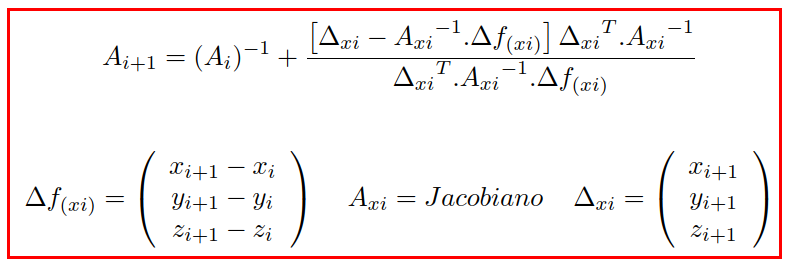

   x=hh(1);  %ASIGNAMOS EL NUEVO VALOR A X
   y=hh(2);  %ASIGNAMOS EL NUEVO VALOR A Y
   z=hh(3);  %ASIGNAMOS EL NUEVO VALOR A Z
    k=1;
    a=[1 2 3];
    b=[1 2 3];
    printt=[a;b];
   while(k<=str2double(answer{5}))
       sistema_evaluado=eval(matrixx); %EVALUAMOS EL SISTEMA CON X-Y-Z            
       delta_fxs=(sistema_evaluado-nn); % DIFERENCIA ENTRE LOS SISTEMAS EVALUADOS
       nn=sistema_evaluado; % ASIGNAMOS NUEVO SISTEMA EVALUADO 
       jacobianinvert_x_delt=jacobian_invers*delta_fxs ;
       first_part=(hh-num_var')-jacobianinvert_x_delt;
       num_var=hh';
       final_delts_trans_x_jacoinv=hh'*jacobian_invers  ; 
       numerator=first_part*final_delts_trans_x_jacoinv;
       denominator=final_delts_trans_x_jacoinv*delta_fxs ;
       division=numerator./denominator;
       broydenn=jacobian_invers+division;
       kk=broydenn*sistema_evaluado;
       hh=hh-kk;
       jacobian_invers=broydenn; 
       x=hh(1);
       y=hh(2);
       z=hh(3);  
       printt(k,:)=(hh');
       Valores_x=printt(:,1);
        Valores_y=printt(:,2);
        Valores_z=printt(:,3);
        export_dates=[Valores_x,Valores_y,Valores_z];
       k=k+1;                  
   end 
   dates_table=table(Valores_x,Valores_y,Valores_z)

dates_table = 10×3 table
    Valores_x     Valores_y     Valores_z
    _________    ___________    _________

     0.49999       0.0087696    -0.52317 
         0.5       0.0036525    -0.52343 
         0.5      0.00053335    -0.52358 
         0.5      0.00010116    -0.52359 
         0.5     -1.8392e-05     -0.5236 
         0.5      9.8149e-07     -0.5236 
         0.5      6.9191e-09     -0.5236 
         0.5     -1.3559e-11     -0.5236 
         0.5     -9.8723e-14     -0.5236 
         0.5     -5.1788e-16     -0.5236 


xlswrite('RESULTADOS.xlsx',export_dates);